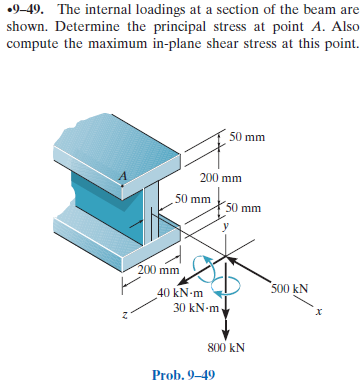

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-49P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-49P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# section properties

% ---------------------------------------------
yc = [50/2 50+200/2 50+200+50/2]*u.mm;
Acz = [200*50 50*200 200*50]*u.mm^2;
Icz = [200*50^3 50*200^3 200*50^3]/sym(12)*u.mm^4;
[yn Qnz Inz] = beam.neutral_axis(yc, Acz, Icz);
Iz = sum(Inz);
% ---------------------------------------------
zc = [200/2 200/2 200/2]*u.mm;
Acy = [50*200 200*50 50*200]*u.mm^2;
Icy = [50*200^3 200*50^3 50*200^3]/sym(12)*u.mm^4;
[zn Qny Iny] = beam.neutral_axis(zc, Acy, Icy);
Iy = sum(Iny);
% ---------------------------------------------
A = sum(Acz);
% ---------------------------------------------

# loads at point A

P = -500*u.kN;
My = -30*u.kN*u.m;
Mz = 40*u.kN*u.m;

# stresses at point A

% ------------
% axial stress
% ------------
sigma_axial = rewrite(P/A, u.MPa);
sigma_axial_vpa = vpa(sigma_axial, 4) %#ok<NASGU> 

$$sigma\_axial\_vpa = -16.67\,\mathrm{MPa}$$

% --------------
% bending stress
% --------------
y = 150*u.mm;
z = 100*u.mm;
sigma_bending = beam.unsymmetric(My, Mz, Iy, Iz, y, z);
sigma_bending = rewrite(sigma_bending, u.MPa);
sigma_bending_vpa = vpa(sigma_bending, 4) %#ok<NASGU> 

$$sigma\_bending\_vpa = -60.78\,\mathrm{MPa}$$

# mohr stresses at point A

sigmax = sigma_axial+sigma_bending;
sigmax_vpa = vpa(sigmax, 4) %#ok<NASGU> 

$$sigmax\_vpa = -77.45\,\mathrm{MPa}$$

sigmay = sym(0)

$$sigmay = 0$$

tauxy = sym(0)

$$tauxy = 0$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle for point A

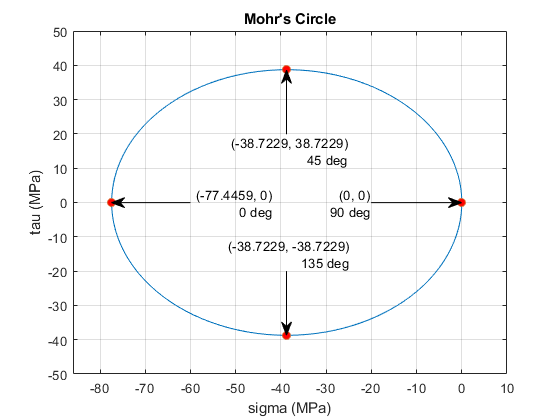

beam.mohr_plot(sigmax, sigmay, tauxy, {'MPa'});
axis([-86 10 -50 50])
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = -60;
      y1 = 0;
    case 2
      x1 = -20;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 20;
    case 4
      x1 = xvals(4);
      y1 = -20;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

assume(old_assum);
clear old_assum;
clear sigma_axial_vpa sigma_bending_vpa;
clear sigmax_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;